## OPTIMAL WT PATH GENERATOR _ alpha v1.1

### Welcome to... path generator program.

#### To run this program,

#### First, fill in the blanks in wind turbine information section

#### Second, prepare constraint.csv

#### Third, please press RUN button below when ready ▽

activeAddr = matlab.desktop.editor.getActiveFilename;
activeAddr = fileparts(activeAddr);
cd(activeAddr)

## User Input

### Wind turbine information

wtPos = [0,0,0]';

wtDir = 0; %deg (Looking into the blade)
wtHeight = 100;
bladeL = 60;
noseL = 15;
homePos = [-30 10 0]';
wtRot = 0;
inspectionDist = 9;
rootDist = 9;
vnum = 1;

### Route contraint input

constraintAddr = "constraint.csv";
tableData = readtable('constraint.csv','VariableNamesLine',2);

 

% nonDirectonal penalty region
nonDirectionalL = size(tableData.pair1,1) - sum(isnan(tableData.pair1));
penaltyRegion = [tableData.pair1(1:nonDirectionalL),tableData.pair2(1:nonDirectionalL)];
penaltyVal = tableData.penaltyVal(1:nonDirectionalL);
penaltyRegion = vertcat(penaltyRegion,fliplr(penaltyRegion));
penaltyVal = [penaltyVal;penaltyVal];

% Directional penalty region
directionalL = size(tableData.initNodeIdx,1) - sum(isnan(tableData.initNodeIdx));
penaltyRegion_direc = [tableData.initNodeIdx(1:directionalL),tableData.endNodeIdx(1:directionalL)];
penaltyVal_direc = tableData.penaltyVal_1(1:directionalL);

% Sum penalty region
penaltyRegion = vertcat(penaltyRegion, penaltyRegion_direc);
penaltyVal = vertcat(penaltyVal,penaltyVal_direc);

% Man input (of time)
manL = size(tableData.value,1) - sum(isnan(tableData.value));
manInputRegion = [tableData.initNodeIdx_1(1:manL),tableData.endNodeIdx_1(1:manL)];
manInputVal = tableData.value(1:manL);

## Main Function 

The program will do the rest. Please Wait.

d2r = pi/180;
r2d = 1/d2r;

%% Inspection point generation 

wtDir = wtDir * d2r;
wtRot = wtRot * d2r;
dcmI2BlPlane = angle2dcm(wtDir,0,wtRot,'zyx');

dcmBlPlane2Bl = [];
dcmBlPlane2Bl{1} = angle2dcm(0,0,120*d2r,'zyx');
dcmBlPlane2Bl{2} = angle2dcm(0,0,0*d2r,'zyx');
dcmBlPlane2Bl{3} = angle2dcm(0,0,-120*d2r,'zyx');

wtCore = wtPos + [0 0 -wtHeight]';
nosePos = wtCore + dcmI2BlPlane' * [-noseL, 0, 0]';

rootWp = zeros(3,4,3); % bl#, fix#, posNed
tipWp = zeros(3,4,3);
centerWp = zeros(3,4,3);
for blNum = 1:3
    tempRoot = [];
    tempTip = [];
    tempCenter = [];
    for fixNum = 0:3
        tempRoot(fixNum+1,:) = [inspectionDist * cos(pi/2*fixNum), inspectionDist * sin(pi/2*fixNum), -rootDist];
        tempTip(fixNum+1,:) = [inspectionDist * cos(pi/2*fixNum), inspectionDist * sin(pi/2*fixNum), -bladeL];
        tempCenter(fixNum+1,:) = [inspectionDist * cos(pi/2*fixNum), inspectionDist * sin(pi/2*fixNum), -(bladeL+rootDist)/2];
    end
    rootWp(blNum,:,:) = (wtCore + dcmI2BlPlane' * dcmBlPlane2Bl{blNum}' * tempRoot')';
    tipWp(blNum,:,:) = (wtCore + dcmI2BlPlane' * dcmBlPlane2Bl{blNum}' * tempTip')';
    centerWp(blNum,:,:) = (wtCore + dcmI2BlPlane' * dcmBlPlane2Bl{blNum}' * tempCenter')';
end

totalWp(1,:,:,:) = rootWp;
totalWp(2,:,:,:) = tipWp;
totalWp(3,:,:,:) = centerWp;

disp("Node generation complete!")

Node generation complete!


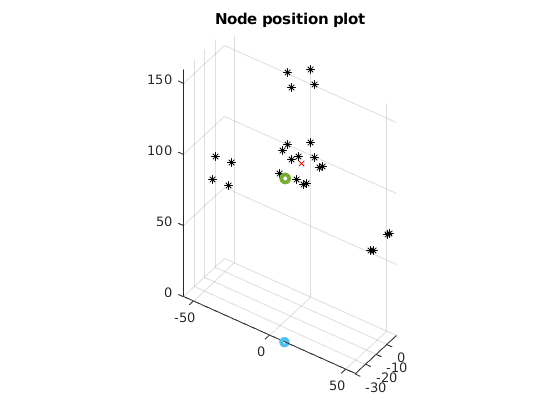


figure(1)
clf
hold on
grid on
for j = 1:3
tempRoot = reshape(rootWp(j,:,:),4,3);
tempTip = reshape(tipWp(j,:,:),4,3);
tempCenter = reshape(centerWp(j,:,:),4,3);
for i = 1:4
plot3(tempRoot(i,2),tempRoot(i,1),-tempRoot(i,3),'k*')
plot3(tempTip(i,2),tempTip(i,1),-tempTip(i,3),'k*')
% plot3(tempCenter(i,2),tempCenter(i,1),-tempCenter(i,3),'k*')
end
end

plot3(wtCore(2),wtCore(1),-wtCore(3),'rx')
plot3(nosePos(2),nosePos(1),-nosePos(3),'o','LineWidth',3)
plot3(homePos(2),homePos(1),homePos(3),'o','MarkerSize',5,'LineWidth',3)
view(35,40)
axis equal
title('Node position plot')
drawnow


%% Network formulation

% A -> connectivity matrix
% C -> cost matrix
N = 24 + 1; % add nose
A = zeros(N,N);
C = zeros(N,N);
C_dist = zeros(N,N);
C_time = zeros(N,N);
IMR = [];

% root to tip connector
for blNum = 1:3
    base = (blNum-1)*8 + 1;
    self = [0 1 0 1;1 0 1 0];
    self = vertcat(self,self);
    rootTip = eye(4);
    region = [self,rootTip;rootTip,self];
    A(base+1:base+size(region,1),base+1:base+size(region,1)) = region;
end

% inter blade connector
region = zeros(8,8);
region12 = region;
region12(1:4,1:4) = ...
    [0 0 0 0;...
    0 0 0 0;...
    0 0 1 0;...
    0 1 0 0];
region13 = region;
region13(1:4,1:4) = ...
    [0 0 0 0;...
    0 0 0 0;...
    0 0 1 0;...
    0 0 0 0];
region23 = region12;
A(2:9,10:25) = [region12,region13];
A(10:17,18:25) = region23;
A(10:25,2:9) = [region12,region13]';
A(18:25,10:17) = region23';

% nose blade connector
temp = zeros(1,N);
for blNum = 1:3
    base = (blNum-1)*8 + 1;
    temp(base+3) = 1;
end
A(1,:) = temp;
A(:,1) = temp';

%% Cost matrix formulation

% % Velocity profile generation
% vFast = 1.5;
% vSlow = 1;
% Vel = zeros(N,N);
% for i = 1:N
%     for j = 1:N
%         if i~=j
%             Vel(i,j) = vFast;
%         end
%     end
% end
% 
% % Slow speed region
% slowRegion = [14 10];
% for i = size(slowRegion,1)
%     Vel(slowRegion(i,1),slowRegion(i,2)) = vSlow;
% end
velocity = 1.5;
Vel = ones(N,N) * velocity;

% C_dist and C_time calc.
for i = 1:N
    for j = 1:N
        if A(i,j) == 1 && i~=j
            initNod = nodeInterpreter(i);
            targNod = nodeInterpreter(j);
            if initNod.home
                startNodePos = nosePos;
            else
                startNodePos = reshape(totalWp(initNod.rt,initNod.blNum,initNod.fixNum,:),3,1);
            end
            if targNod.home
                endNodePos = nosePos;
            else
                endNodePos = reshape(totalWp(targNod.rt,targNod.blNum,targNod.fixNum,:),3,1);
            end
            if initNod.rt == targNod.rt && initNod.blNum == targNod.blNum
                C_dist(i,j) = norm(endNodePos - startNodePos) * pi/2/sqrt(2);
            else
                C_dist(i,j) = norm(endNodePos - startNodePos);
            end
            % distance to time
            C_time(i,j) = C_dist(i,j) / Vel(i,j);
        end
    end
end

% C calc. with penalty
C = C_time;
for i = 1:size(penaltyRegion,1)
    startIdx = penaltyRegion(i,1);
    endIdx = penaltyRegion(i,2);
    C(startIdx,endIdx) = C(startIdx,endIdx) * penaltyVal(i);
end

for i = 1:size(manInputRegion,1)
    startIdx = manInputRegion(i,1);
    endIdx = manInputRegion(i,2);
    C(startIdx,endIdx) = manInputVal(i);
end

wtGraph = digraph(C);
wtGraph_time = digraph(C_time);
wtGraph_dist = digraph(C_dist);

nPos = zeros(N,1); ePos = zeros(N,1); dPos = zeros(N,1);
for i = 1:N
    Nod = nodeInterpreter(i);
    if Nod.home == 1
        nPos(i) = homePos(1);
        ePos(i) = homePos(2);
        dPos(i) = homePos(3);
    else
        NodPos = reshape(totalWp(Nod.rt,Nod.blNum,Nod.fixNum,:),3,1);
        nPos(i) = NodPos(1);
        ePos(i) = NodPos(2);
        dPos(i) = NodPos(3);
    end
end
xPos = ePos; yPos = nPos; zPos = -dPos;

disp("Cost matrix generation complete!")

Cost matrix generation complete!


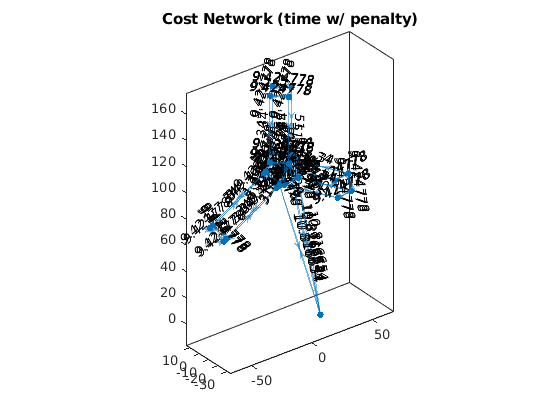


figure(2)
clf
plot(wtGraph,'XData',xPos,'YData',yPos,'ZData',zPos,'Edgelabel',wtGraph.Edges.Weight,'NodeLabel',[],'EdgeFontSize',10)
axis equal
title('Cost Network (time w/ penalty)')
drawnow



% complet-ification
implicitRoute = [];
for i = 1:N
    for j = i:N
        if A(i,j) ~= 1 && i~=j
            [implRoute,d]=shortestpath(wtGraph,i,j,'Method','positive');
            implicitRoute{i,j} = implRoute;
            implicitRoute{j,i} = fliplr(implRoute);
            C(i,j) = d;
            C(j,i) = d;
        end
    end
end

disp("Complefication complete!")

Complefication complete!



disp("Initiate solver!")

Initiate solver!


%% Solve!
map.N = N;
map.capacity = bladeL * 12 / vnum;
% map.capacity = 1e10;
map.C = C;
map.vnum = vnum;
map.oblig = ...
    [4,8;3,7;2,6;5,9;...
    12,16;11,15;10,14;13,17;...
    20,24;21,25;18,22;19,23];

solve_complete = false;
tic
while ~solve_complete
    [routeResult,score] = TSP_solver(map);
    if score == -1
        map.capacity = map.capacity * 1.1;
    else
        solve_complete = true;
    end
end
solve_time = toc;
disp("Solution found! Terminating solver.")

Solution found! Terminating solver.


disp("Solve time : "+num2str(solve_time))

Solve time : 1.0466



% Home edition
homeAddNode = [];
for i = 1:size(routeResult,1)
    if routeResult(i,end) ~= 0
        homeAddNode(i) = 1;
    else
        zeroRoute = find(routeResult(i,:)==0);
        zeroRouteIdx = zeroRoute(1);
        routeResult(i,zeroRouteIdx) = 1;
        homeAddNode(i) = 0;
    end
end
routeResult = horzcat(routeResult,homeAddNode');

% Route extraction
Nr = size(routeResult,2);
routePos = zeros(map.vnum,3,Nr);
for v = 1:map.vnum
    for i = 1:size(routeResult,2)
        routeNod = nodeInterpreter(routeResult(v,i));
        if routeNod.home
            routePos(v,:,i) = nosePos;
        else
            routePos(v,:,i) = reshape(totalWp(routeNod.rt,routeNod.blNum,routeNod.fixNum,:),3,1);
        end
    end
end

% Route decipher
routeResultDec = [];
for v = 1:map.vnum
    routeResultDec{v} = routeResult(v,1);
    addRoute = [];
    for i = 1:Nr-1
        ni = routeResult(v,i);
        nf = routeResult(v,i+1);
        if nf == 0
            addRoute = 0;
        else
            if A(ni,nf) == 0
                hiddenRoute = implicitRoute{ni,nf};
                hiddenRoute(1) = [];
                addRoute = hiddenRoute;
            else
                addRoute = nf;
            end
        end
        routeResultDec{v}(end+1:end+length(addRoute)) = addRoute;
    end
end

Matrix index is out of range for deletion.


% Deciphered route extraction
routePosDec = [];
for v = 1:map.vnum
    Nd = size(routeResultDec{v},2);
    for i = 1:Nd
        routeNod = nodeInterpreter(routeResultDec{v}(i));
        if routeNod.home
            routePosDec{v}(:,i) = nosePos;
        else
            routePosDec{v}(:,i) = reshape(totalWp(routeNod.rt,routeNod.blNum,routeNod.fixNum,:),3,1);
        end
    end
end

disp("Result decoding complete")

% Evaluate route
travelDistance = 0;
travelTime = 0;
for i = 1:length(routeResultDec{1})-2
    initNod = routeResultDec{1}(i);
    endNod = routeResultDec{1}(i+1);
    travelDistance = travelDistance + C_dist(initNod,endNod);
    travelTime = travelTime + C_time(initNod,endNod);
end

disp(" ")
disp(" ")
disp("========================")
disp("RESULT : ")
totalScore = score
travelDistance
travelTime
disp(routeResult)
disp(" ")
disp("Optimal route job explanation")
% Route explanation
surfaceName = [];
surfaceName{1} = ["TE","DNSS","LE","UPSS"];
surfaceName{2} = ["TE","RTSS","LE","LTSS"];
surfaceName{3} = ["TE","UPSS","LE","DNSS"];
verbalRoute = [];
for i = 1:length(routeResultDec{1})-1
    initNod = routeResultDec{1}(i);
    endNod = routeResultDec{1}(i+1);
    initNod = nodeInterpreter(initNod);
    endNod = nodeInterpreter(endNod);
    if initNod.home == 1
        verbalRoute = vertcat(verbalRoute,"PP(NoseToRoot) Nose TO Root @ blade #" + num2str(endNod.blNum-1));
    elseif endNod.home == 1
        verbalRoute = vertcat(verbalRoute,"MissionComplete");
    else
        if initNod.rt == 1
            if endNod.rt == 1
                verbalRoute = vertcat(verbalRoute,"PP(RootToRoot) - " + "#" + num2str(initNod.blNum-1) + " "...
                    + surfaceName{initNod.blNum}(initNod.fixNum) + " root TO #" + num2str(endNod.blNum-1) + " "...
                    + surfaceName{endNod.blNum}(endNod.fixNum) + " root");
            else
                verbalRoute = vertcat(verbalRoute,"BF(RootToTip) - #" + num2str(initNod.blNum-1) + " " + surfaceName{initNod.blNum}(initNod.fixNum));
            end
        elseif initNod.rt == 2
            if endNod.rt == 2
                verbalRoute = vertcat(verbalRoute,"PP(TipToTip) - #" + num2str(initNod.blNum-1) + " " + surfaceName{initNod.blNum}(initNod.fixNum)...
                    + " TO " + surfaceName{endNod.blNum}(endNod.fixNum));
            else
                verbalRoute = vertcat(verbalRoute,"BF(TipToRoot) - #" + num2str(initNod.blNum-1) + " " + surfaceName{initNod.blNum}(initNod.fixNum));
            end
        else
            verbalRoute = vertcat(verbalRoute,"ERROR");
        end
    end
end
for i = 1:length(verbalRoute)
    verbalRoute(i) = "Job #" + num2str(i) + " : " + verbalRoute(i);
end
disp(verbalRoute)


%% Plot
figure(11)
clf
hold on
grid on
for j = 1:3
tempRoot = reshape(rootWp(j,:,:),4,3);
tempTip = reshape(tipWp(j,:,:),4,3);
for i = 1:4
plot3(tempRoot(i,2),tempRoot(i,1),-tempRoot(i,3),'k*')
plot3(tempTip(i,2),tempTip(i,1),-tempTip(i,3),'k*')
end
end
plot3(wtCore(2),wtCore(1),-wtCore(3),'rx')
plot3(nosePos(2),nosePos(1),-nosePos(3),'mo','MarkerSize',3,'LineWidth',7)
plot3(homePos(2),homePos(1),homePos(3),'o','MarkerSize',1,'LineWidth',3)
view(35,40)

axis equal

% route plot
for v = 1:map.vnum
    plot3(reshape(routePos(v,2,:),1,Nr),reshape(routePos(v,1,:),1,Nr),-reshape(routePos(v,3,:),1,Nr),'*--','LineWidth',1)
end
for i = 1:N
    Nod = nodeInterpreter(i);
    if Nod.home ~= 1
        NodPos = reshape(totalWp(Nod.rt,Nod.blNum,Nod.fixNum,:),3,1);
        text(NodPos(2),NodPos(1),-NodPos(3),num2str(i))
    end
end
title('Raw route result')
drawnow


figure(12)
clf
hold on
grid on
for j = 1:3
tempRoot = reshape(rootWp(j,:,:),4,3);
tempTip = reshape(tipWp(j,:,:),4,3);
for i = 1:4
plot3(tempRoot(i,2),tempRoot(i,1),-tempRoot(i,3),'k*')
plot3(tempTip(i,2),tempTip(i,1),-tempTip(i,3),'k*')
end
end
plot3(wtCore(2),wtCore(1),-wtCore(3),'rx')
plot3(nosePos(2),nosePos(1),-nosePos(3),'mo','MarkerSize',3,'LineWidth',7)
plot3(homePos(2),homePos(1),homePos(3),'o','MarkerSize',1,'LineWidth',3)
view(35,40)
axis equal

% deciphered route plot
for v = 1:map.vnum
    plot3(routePosDec{v}(2,:),routePosDec{v}(1,:),-routePosDec{v}(3,:),'*--','LineWidth',1)
end
title('Decoded result (final result)')
drawnow
% title('Final result')
% drawStl(stlAddr,12)

disp("Program finished.")